# Comic-Like Effect

Sherry Zhou

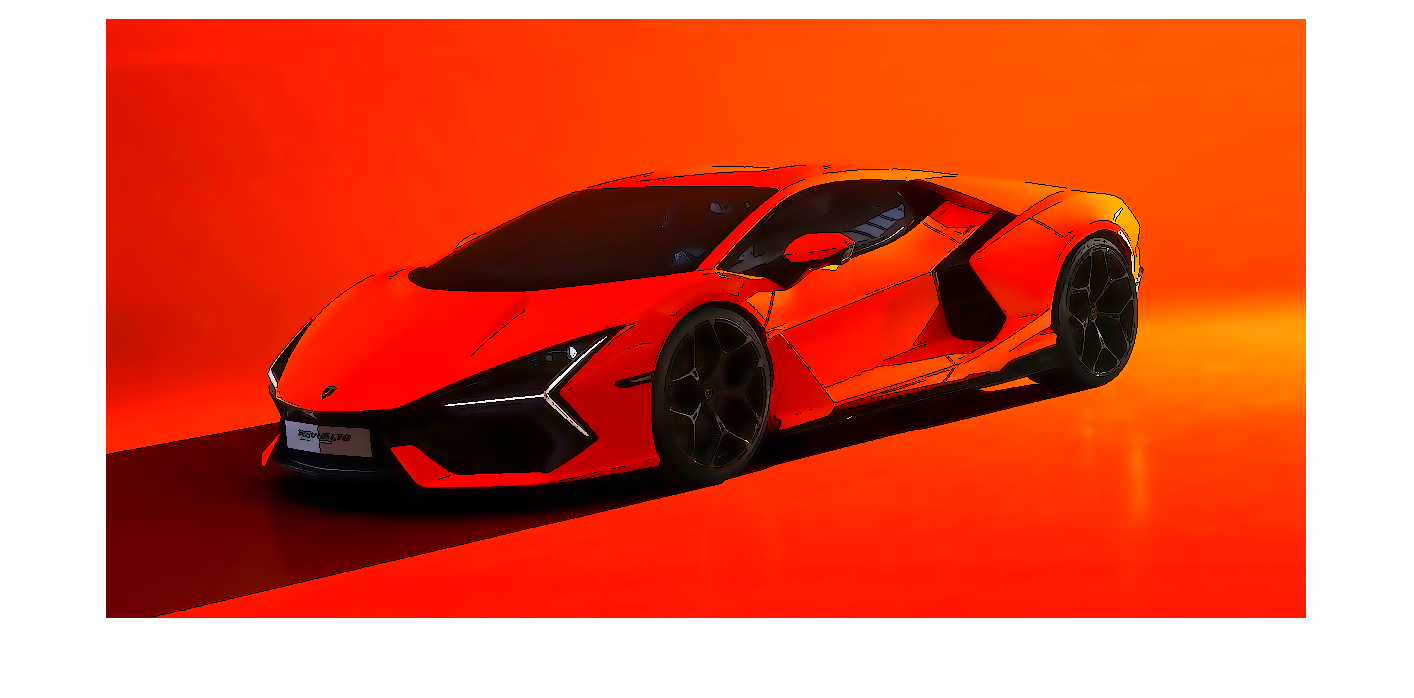

clc,clear,close all;

img = imread('car.jpeg');
img = double(img)/255;

result1 = bilateral_filter(double(img),8,[3 0.1]);
result2 = edge_detect(result1);
result3 = color_adjust(result2);
imshow(result3)

% Bilateral filtering function

function img_f = bilateral_filter(img,d,arg) 
    img = applycform(img,makecform('srgb2lab'));  
    [x,y,~]=size(img);
    img_f=zeros(x,y);
    % Expand the overall image boundary to ensure the generated image is consistent with the original image dimensions
    extract = extract_region(img,d,x,y);
    length = 2*d+1;
    % Calculate distance weight using Gaussian function based on Euclidean distance
    G = fspecial('gaussian',[length,length],arg(1));
    S = zeros(length,length);
	% Calculate value weight for each pixel in the image
    for i=1+d:x+d  
        for j=1+d:y+d
        	% Calculations are performed on the three channels of the color image
            rawvalue = extract(i-d:i+d,j-d:j+d,1:3);   
            da = rawvalue(:,:,1)-extract(i,j,1);  
            db = rawvalue(:,:,2)-extract(i,j,2);  
            dc = rawvalue(:,:,3)-extract(i,j,3);  
            S = exp(-(da.^2+db.^2+dc.^2)/(2*(arg(2)*100)^2));  
            % Calculate total weight
            H = S.*G;  
            % Normalize the weights
            H = H./sum(H(:));  
            % Calculate the value of each point
            img_f(i-d,j-d,1) = sum(sum(rawvalue(:,:,1).*H));   
            img_f(i-d,j-d,2) = sum(sum(rawvalue(:,:,2).*H));      
            img_f(i-d,j-d,3) = sum(sum(rawvalue(:,:,3).*H));   
        end   
    end  
    img_f = applycform(img_f,makecform('lab2srgb'));  
end

% Expand image boundary
function extract = extract_region(img,w,x,y)
    extract = zeros(x + 2 * w, y + 2 * w, 3); 
    % Keep the original image in the middle
    extract(w +1:w + x,w + 1:w + y,1:3) = img;  
    % Expand each side by (window side length + 1) / 2
    extract(1:w,w + 1:w + y,1:3) = img(w:-1:1,:,1:3);  
    extract(end - w:end,w + 1:w + y,1:3) = img(end:-1:end - w,:,1:3);  
    extract(:,1:w,1:3) = extract(:,2 * w:-1:w + 1,1:3);  
    extract(:,y + w+1:y + 2*w,1:3) = extract(:,y + w:-1:y + 1,1:3);  
end

% Extract image edges
function img_f = edge_detect(img)
    img_gray = rgb2gray(img);
    % Set to Sobel operator, threshold is 0.02
    edge_m = uint8(edge(img_gray, 'sobel', 0.02));
    img_blur = uint8(img*255);
    % Subtract edges from each layer
    img_f(:,:,1) = img_blur(:,:,1) - img_blur(:,:,1) .* edge_m;
    img_f(:,:,2) = img_blur(:,:,2) - img_blur(:,:,2) .* edge_m;
    img_f(:,:,3) = img_blur(:,:,3) - img_blur(:,:,3) .* edge_m;
end

% Adjust image saturation
function img_res = color_adjust(img)
    img_double = double(img);
    img_gray = double(rgb2gray(img));
    S_template = img_double;
    % Use the grayscale image of the original image as a template to complete interpolation and extrapolation
    S_template(:,:,1)=img_gray; 
    S_template(:,:,2)=img_gray;
    S_template(:,:,3)=img_gray;
    % Interpolation and extrapolation
    img_res = (-1).*S_template  +2.*img_double;
    img_res = uint8(img_res);
end